# Lab - Eigenvalues

**Topics: **eigenvalues, eigenvectors, natural frequencies, saving and loading data

## Set up system

clear, clc, format short

**Set up system:**

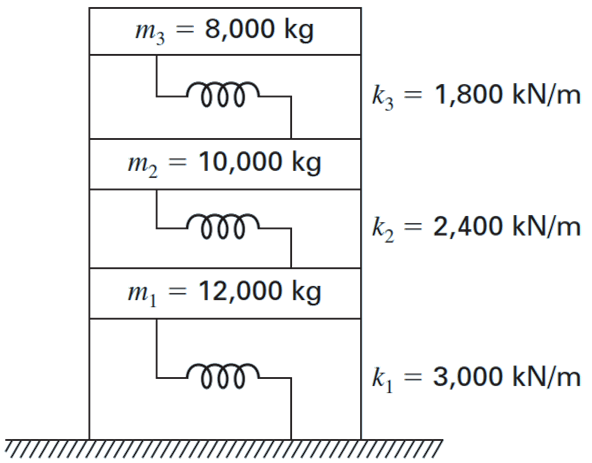

 % spring constant data in kN/m, need N/m
scaleToNewtons = 1000;

k1 = 3000*scaleToNewtons;
k2 = 2400*scaleToNewtons;
k3 = 1800*scaleToNewtons;

m1 = 12000;
m2 = 10000;
m3 = 8000;


$A-\lambda I$= $\begin{array}{l}
\left(\frac{k_1 +k_2 }{m_1 }-\omega_n^2 \right)X_1 -\frac{k_2 }{m_1 }X_2 =0\\
-\frac{k_2 }{m_2 }X_1 +\left(\frac{k_2 +k_3 }{m_2 }-\omega_n^2 \right)X_2 -\frac{k_3 }{m_2 }X_3 =0\\
-\frac{k_3 }{m_3 }X_2 +\left(\frac{k_3 }{m_3 }-\omega_n^2 \right)X_3 
\end{array}$

A = [(k1+k2)/m1  -k2/m1       0;
     -k2/m2      (k2+k3)/m2  -k3/m2;
      0          -k3/m3       k3/m3]

A =    450  -200     0
  -240   420  -180
     0  -225   225


## **Calculate eigenvalues**

[V, D] = eig(A)

V =    -0.5879   -0.6344    0.2913
    0.7307   -0.3506    0.5725
   -0.3471    0.6890    0.7664


D =   698.5982         0         0
         0  339.4779         0
         0         0   56.9239



fprintf(['\x3bb(1) value is %0.2f\n' ...
    '\x3bb(2) value is %0.2f\n' ...
    '\x3bb(3) value is %0.2f'], ...
    D(1,1), D(2,2), D(3,3))

λ(1) value is 698.60
λ(2) value is 339.48
λ(3) value is 56.92

**Natural frequencies (in Hz) **$\omega_n =\frac{\sqrt{\lambda }}{2\pi }$

wn = sqrt(diag(D))/(2*pi)

wn =     4.2066
    2.9324
    1.2008


## Prepare data for storage

wn_sorted = sort(wn)

wn_sorted =     1.2008
    2.9324
    4.2066


**Match sorted eigenvalues with eigenvectors**

Find the original location for the frequencies so we can associate frequencies with eigenvectors

for mode = 1:length(wn_sorted)

    index = find(wn == wn_sorted(mode));
    if mode == 1
        frequency1 = wn(index);
        eigenvector1 = V(:,index);
    elseif mode == 2
        frequency2 = wn(index);
        eigenvector2 = V(:,index);
    elseif mode == 3
        frequency3 = wn(index);
        eigenvector3 = V(:,index);
    end

end

## Save the data

save mode frequency1 eigenvector1...
          frequency2 eigenvector2...
          frequency3 eigenvector3

## Load the data

Can't load if it doesn't exist

if exist('mode.mat','file')
    load mode.mat
end


## Plot the 3 modes of oscillation 

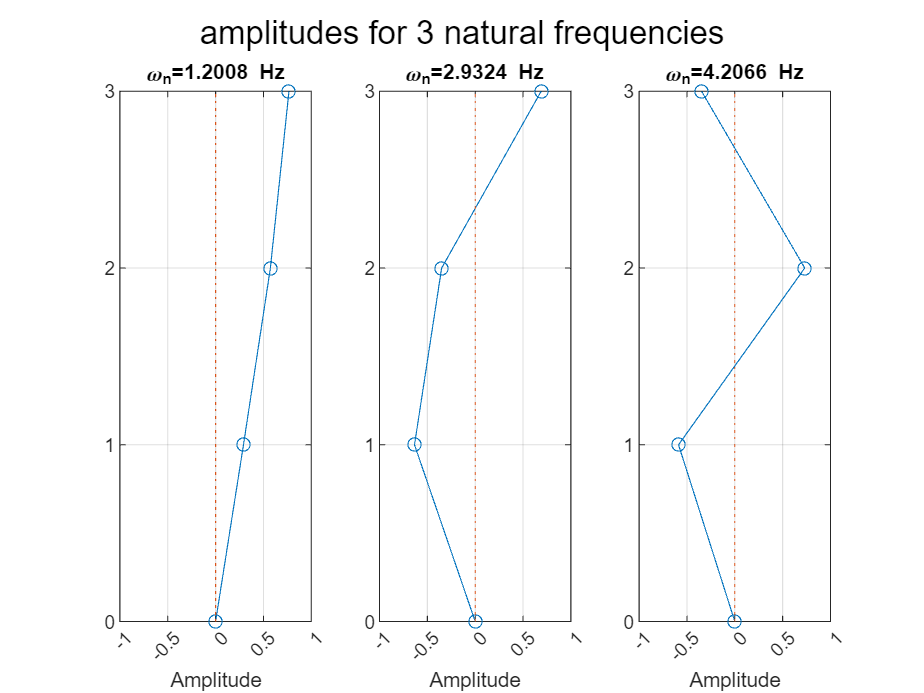

if exist('frequency1','var')
    story = 0:3;
    V = [eigenvector1,eigenvector2,eigenvector3];
    xlimit = ceil(max(abs(V)));
    figure(1)
    sgtitle 'amplitudes for 3 natural frequencies'

    subplot(1,3,1)
    makePlot(eigenvector1,story,frequency1,xlimit(1));
  
    subplot(1,3,2)

    makePlot(eigenvector2,story,frequency2,xlimit(2));
    
    subplot(1,3,3)

    makePlot(eigenvector3,story,frequency3,xlimit(3));
  

else
    disp('cant plot required vars missing')
end

## Helper function

function makePlot(xVal, yVal, frequency, xlimit)
% makePlot - set up each of 3 plots the same
% INPUT: 
%   xVal - x values for plot
%   yVal - y values for plot
%   the natural frequency
%   xlimit - maximum x value to scale the x axis
    plot([0; xVal], yVal, 'o-', ...
        [0 0], [0  max(yVal)], ':') % centerline
    axis([-xlimit xlimit ...
          0  max(yVal)])
    xticks([-xlimit:0.5:xlimit])
    yticks(yVal)
    title(['\omega_n=' num2str(frequency) ...
        ' Hz'])
    xlabel 'Amplitude'
    grid on
end